## Data preprocessing

#### Load data and functions

% Empty workspace
clear all
close all

% Define working folder
userpath('D:\Llamadas');

% Load functions
addpath(fullfile(userpath,'SIDE','Functions'));

%Load Data
calls = readtable(fullfile(userpath,'Datos','calls_vlc.csv'));

#### Restructure Data

Group coordinates by day

% Define initial time
group = 1;

% Define empty objects
callsAllDay = struct;
coords = [];

% Loop table rows
for i = 1:height(calls)
    newGroup = calls{i,"t"};
    if group == newGroup
        coords = [coords; calls{i,"x"}, calls{i,"y"}];
    else
        coords = [];
        group = newGroup;
        coords = [coords; calls{i,"x"}, calls{i,"y"}];
    end
    callsAllDay(newGroup).Coords = coords;
end

% Save data
%save(fullfile(userpath,'SIDE/Data/callsAllDay'),"callsAllDay")
load(fullfile(userpath,'SIDE/Data/callsAllDay'))

Group data by week and rescale

% Define time set-up

% Delta time
dt = 1;
% Number of weeks
N = max(calls{:,"semana"});
% Sequence of weeks
t = 0:dt:dt*(N-1);

% Define space set-up

% Number of divisions of region of interest
J = 101;
% Division of region of interest
s = linspace(0,36,J);

% Define time and space transformation parameters

% Number of weeks data
numWeeks = ceil(length(callsAllDay)/7);
% Prelocate empty array
weekNum = zeros(numWeeks,1);
% Shift factor (move coordinates to lower left origin)
shift = [min(calls{:,"x"}), min(calls{:,"y"})];
% Scale factor (scale coordinates to fit into a 36 x 36 square)
scale = [264, 353];

% Rescale and shift data to agreggate their coordinates by weeks

% Initialize counters
i = 1;
k = 1;

%Define empty object
callsAllWeek = struct;
dayNum = zeros(length(callsAllDay),1)

while i < length(callsAllDay)
   callsAllWeek(k).Coords = [];
   for j = 0:6  %Cluster in weeks and put on 36x36 square
    if ~isempty(callsAllDay(i).Coords)
        callsAllDay(i).Coords(:,1) = (callsAllDay(i).Coords(:,1) - shift(1))/scale(1);
        callsAllDay(i).Coords(:,2) = (callsAllDay(i).Coords(:,2) - shift(2))/scale(2);
        callsAllWeek(k).Coords = [callsAllWeek(k).Coords;callsAllDay(i).Coords];
    end
    callsAllWeek(k).Coords = CleanfromNans(callsAllWeek(k).Coords);
    callsAllWeek(k).Coords = CleanOutliers(callsAllWeek(k).Coords);
    dayNum(i) = size(callsAllDay(i).Coords,1);
    weekNum(k) = weekNum(k) + length(callsAllDay(i).Coords);
    i = i+1;
   end
   k = k+1;
end
weekNum(end) = [];
N = length(weekNum);

### Temporal Analysis

#### Weekly number of events

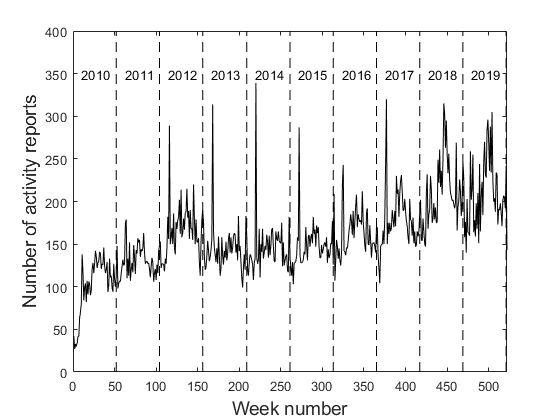

% Temporal trend per week
figure()
plot(weekNum,'k')
hold on 
weekinter = 365/7;
for i = 1:10
    yearstr = num2str(2009+i);
    text(round((i-1)*weekinter)+10,350,yearstr);
    plot([round(i*weekinter),round(i*weekinter)],[0,400],'k--')
end
xlabel('Week number','Fontsize',14)
ylabel('Number of activity reports','Fontsize',14)
axis([0, length(weekNum), 0 400])

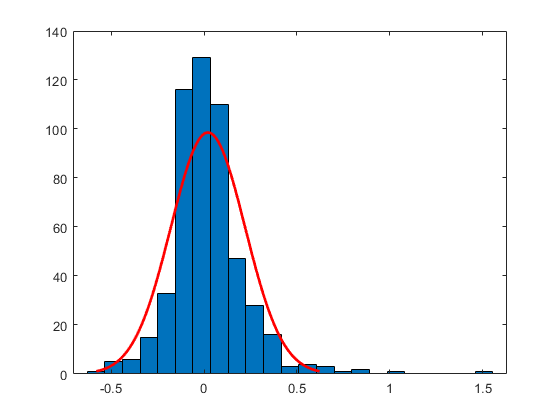

%Shapiro-Wilk test
for i = 1:length(weekNum)-1
    Stat(i) = (weekNum(i+1) - weekNum(i))/weekNum(i);
end
figure()
histfit(Stat)

% Try to remove or modify outliers so the data follow a normal distribution

% Calculate average number of events per year
meansYear = struct;
yearWeeks = 52;
yearIn = 1;
for i = 1:floor(length(weekNum)/yearWeeks)
    yearEnd = i*yearWeeks;
    if (i == floor(length(weekNum)/yearWeeks))
        yearEnd = length(weekNum);
    end
    meansYear(i).mean = mean(weekNum(yearIn:yearEnd));
    meansYear(i).sd = std(weekNum(yearIn:yearEnd));
    yearIn = yearEnd + 1;
end

i=1;
j=1;
indexremoved = [];
while i <= length(Stat)
    if(Stat(i) < -0.50) || (Stat(i) > 0.50)
        Stat(i) = [];
        indexremoved(end+1) = j;
    else
        i = i+1;
    end
    j= j+1;
end
[H,P,~] = swtest(Stat,0.05,0);
disp(['P = ',num2str(P)])

P = 0.021195


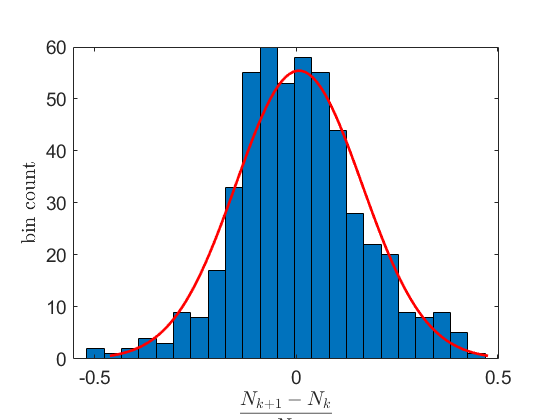

figure()
histfit(Stat)
h = findobj(gca,'Type','patch');
set(h,'FaceColor',[.8 .8 1],'EdgeColor','k')
TrimFig(0.8);
SetFontSize(14);
xlabel('$$\frac{N_{k+1} - N_k}{N_k}$$','Interpreter','latex','Fontsize',15)
ylabel('bin count','Interpreter','latex','Fontsize',15)

set(gcf,'PaperPositionMode','auto')

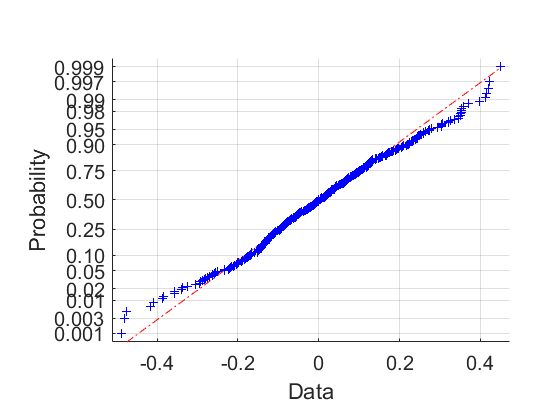

figure()
normplot(Stat)
TrimFig(0.8);
SetFontSize(15);
title('')

set(gcf,'PaperPositionMode','auto')

%Levene Test for homoscedasticity
Years = struct;
yearWeeks = 52;
yearIn = 1;
for i = 1:floor(length(Stat)/yearWeeks)
    yearEnd = i*yearWeeks;
    if (i == floor(length(Stat)/yearWeeks))
        yearEnd = length(Stat);
    end
    Years(i).data = Stat(yearIn:yearEnd - length(find((indexremoved >= yearIn) & (indexremoved <= yearEnd))))';
    yearIn = yearEnd + 1;
end

yearsArray = [];
for i = 1:length(Years)
    Years(i).ones = [Years(i).data i*ones(length(Years(i).data),1)];
    yearsArray = [yearsArray; Years(i).ones];
end

% Homocedasticity test
Levenetest(yearsArray,0.05) % data is homoscedastic

The number of samples are: 9

-----------------------------
 Sample    Size      Variance
-----------------------------
   1       50         0.0268
   2       52         0.0208
   3       51         0.0308
   4       50         0.0242
   5       49         0.0234
   6       50         0.0178
   7       50         0.0206
   8       51         0.0185
   9       88         0.0308
-----------------------------
 
Levene's Test for Equality of Variances F=1.5601, df1= 8, df2=482
Probability associated to the F statistic = 0.1343
The associated probability for the F test is equal or larger than 0.05
So, the assumption of homoscedasticity was met.


%MLE of variance (see any text on stochastic volatility models)
weekN = length(weekNum);
Sigma2MLE = sum(log(weekNum(2:end))-log(weekNum(1:end-1)))/weekN - (log(weekNum(end) - log(weekNum( ...
    1))))^2/(weekN^3);
SigmaMLE = sqrt(Sigma2MLE)

SigmaMLE = 0.0484

## Non-parametric estimators

### Pair correlation estimator

% Radial distances
r = 0.1:0.5:3;

% Define empty objects

% Amplitude of fitted GRBF
Aest = zeros(N,1);
% Kernel width of fitted GRBF
lkernelest = zeros(N,1);
% Non-parametric estimate of the PCAF
gest = zeros(length(r),N);

% PCAF per week
for i = 1:N
    [Aest(i),lkernelest(i),gest(:,i)] = PairCorrFunc(r,callsAllWeek(i).Coords,s);
end

%save(fullfile(userpath,'SIDE/Data/PCAF_PCCF'))
load(fullfile(userpath,'SIDE/Data/PCAF_PCCF'))

### Pair correlation estimator

% Amplitude of fitted GRBF
Acrossest = zeros(N,1);
% Kernel width of fitted GRBF
lkernelcrossest = zeros(N,1);
% Non-parametric estimate of the PCCF
gcrossest = zeros(length(r),N);

%PCCF per week
for i = 2:N
    [Acrossest(i),lkernelcrossest(i),gcrossest(:,i)] = PairCrossCorrFunc(r,callsAllWeek(i).Coords,callsAllWeek(i-1).Coords,s);
end

%save(fullfile(userpath,'SIDE/Data/PCAF_PCCF'))
load(fullfile(userpath,'SIDE/Data/PCAF_PCCF'))

### PACF and PCCF plots

% Define parameters

%Setup space

% Delta space
ds = (max(s)-min(s))/(J-1);
% Support length of basis functions
l = 5;
% Spatial limits on basis representation
smax = s(end)-l;    
smin = l;
[s1,s2] = meshgrid(s,s);

% Set up gaussian field
gaussf = @(s1,s2,mu1,mu2,sigma21,sigma22) exp(-(s1-mu1).^2/sigma21-(s2-mu2).^2/sigma22);
mu1 = (s(end)-s(1))/2 + s(1);
mu2 = (s(end)-s(1))/2 + s(1);

% Boolean to save figures
savefigures = 'n';

Parametric estimation of log PCAF and log PCCF

%Parametric estimation of log(g_{k,k})
[Anoptim,lnoptim] = MethodContrast(r(2:length(r)),exp(mean(log(gest(2:end,2:end)),2)),'RBF',r(2),r(length(r)));
ObservedCovMean = Anoptim*gaussf(s1,s2,mu1,mu2,lnoptim,lnoptim);

%Parametric estimation of log(g_{k,k+1})
[Akoptim,lkoptim] = MethodContrast(r(3:end),exp(mean(log(gcrossest(3:end,2:end)),2)),'RBF',r(3),r(end));
ObservedCrossCovMean = Akoptim*gaussf(s1,s2,mu1,mu2,lkoptim,lkoptim);

%Nonparametric estimation of IDE Kernel using deconvolution with some regularization
Kernelest = real(deconvwnr(ObservedCrossCovMean,ObservedCovMean,0.0000001))/ds^2;

%Parametric reduction
Koptim = @(s1,s2,par) ds^2*sum(sum((par(1)*exp(-(s1-mu1).^2/par(2)-(s2-mu2).^2/par(2)) - Kernelest).^2));
parest = fminsearch(@(par) Koptim(s1,s2,par),[1,1]);
Anoptim = parest(1);
lnoptim = parest(2);
Kernelest = Anoptim*gaussf(s1,s2,mu1,mu2,lnoptim,lnoptim);
midind = ceil(J/2);

Average log PCAF and log PCCF

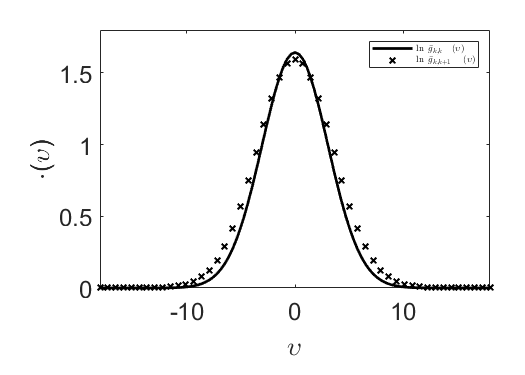

% Figure position
figure('Position',[100,100,700*0.75,500*0.75]);

% Observe cross cov mean
diagCrossCovMean = diag(ObservedCrossCovMean);

%Plot log PCAF and PCCF
plot(s-s(midind),diag(ObservedCovMean),'k','Linewidth',2); hold on
plot(s(1:2:end)-s(midind),diagCrossCovMean(1:2:end),'kx','Linewidth',1.5)

% Set labels
xlabel('\upsilon')
ylabel('\cdot(\upsilon)')

% Set plot parameters
SetFontSize(18);
TrimFig(0.9)
leg = legend('$$\ln~\bar{g}_{k,k}~~~(\upsilon)$$','$$\ln~\bar{g}_{k,k+1}~~~~(\upsilon)$$');
set(leg,'interpreter','latex','Fontsize',7);
set(gcf,'PaperPositionMode','auto');
axis([-15,15,0,1.8])

xlim([-18.0 18.0])
ylim([0.00 1.80])

if savefigures == 'y'
        print -dpng -r600  AutoCov.png
end

Mixing Kernel

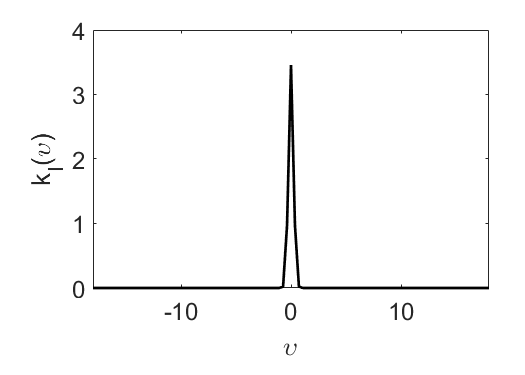

% Figure position
figure('Position',[100,100,700*0.75,500*0.75]);

%Plot estimates kernel
plot(s-s(midind),diag(Kernelest),'k','Linewidth',2)

% Set labels
xlabel('\upsilon')
ylabel('k_I(\upsilon)')

% Set plot parameters
SetFontSize(18);
TrimFig(0.9)
axis([-18 18 0 4.0])

set(gcf,'PaperPositionMode','auto')
if savefigures == 'y'
        print -dpng -r600  Kernel.png
end

Average log PCAF (radial distances)

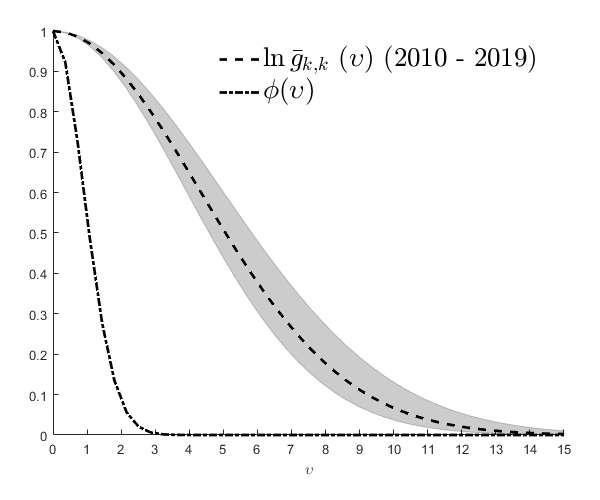

% Figure position
figure('Position',[100,100,600,500]);

%Parametric estimation of log(g_{k,k}) (2010-2015)
[Anoptim,lnoptim] = MethodContrast(r(2:end),exp(mean(log(gest(2:end,1:261)),2)),'RBF',r(2),r(end));
InitObservedCovMean = Anoptim*gaussf(s1,s2,mu1,mu2,lnoptim,lnoptim);
%Parametric estimation of log(g_{k,k}) (2015-2019)
[Anoptim,lnoptim] = MethodContrast(r(2:end),exp(mean(log(gest(2:end,261:end)),2)),'RBF',r(2),r(end));
FinalObservedCovMean = Anoptim*gaussf(s1,s2,mu1,mu2,lnoptim,lnoptim);

% Plot average of log(g_{k,k}) (whole period)
plot(s(1:midind),ObservedCovMean(midind:end,midind)/max(max(ObservedCovMean)),'k--','LineWidth',2); hold on           %Estimated noise Kernel
%plot(s(1:midind),InitObservedCovMean(midind:end,midind)/max(max(InitObservedCovMean)),'g--','LineWidth',1)           %Estimated noise Kernel
%plot(s(1:midind),FinalObservedCovMean(midind:end,midind)/max(max(FinalObservedCovMean)),'b--','LineWidth',1)           %Estimated noise Kernel
plot(s,exp(-(s).^2/(2*0.8106)),'k-.','LineWidth',2)           %Estimated noise Kernel
xlabel('\upsilon','FontSize',12)
xticks(0:1:15);
yticks(0:0.1:1);
axis([0 15 0 1])
SetFontSize(10);

% Plot range of average of log(g_{k,k})
[Anoptim,lnoptim] = MethodContrast(r(2:end),exp(mean(log(gest(2:end,1:end)),2) + 2*std(log(gest(2:end,1:end))')'),'RBF',r(2),r(end));
UpperLimit = Anoptim*gaussf(s1,s2,mu1,mu2,lnoptim,lnoptim);
[Anoptim,lnoptim] = MethodContrast(r(2:end),exp(mean(log(gest(2:end,1:end)),2) - 2*std(log(gest(2:end,1:end))')'),'RBF',r(2),r(end));
LowerLimit = Anoptim*gaussf(s1,s2,mu1,mu2,lnoptim,lnoptim);
jbfill(s(1:midind-8),UpperLimit(midind:end-8,midind)'/max(max(UpperLimit)),LowerLimit(midind:end-8,midind)'/max(max(LowerLimit)),'k', 'k', 1, 0.2);
TrimFig(0.9);
set(gca, 'Box', 'off' );

% Set legend
%leg = legend('$$\ln\bar{g}_{k,k}~(\upsilon)$$ (2010-2019)','$$\ln\bar{g}_{k,k}~(\upsilon)$$  (2010-2015)','$$\ln\bar{g}_{k,k}~(\upsilon)$$  (2015-2019)','$$\phi(\upsilon)$$')
leg = legend('$$\ln\bar{g}_{k,k}~(\upsilon)$$ (2010 - 2019)','$$\phi(\upsilon)$$');
set(leg,'Interpreter','latex','Fontsize',20);
set(leg,'Position',get(leg,'Position') - [0.02 0 0 0]);
legend('boxoff');


if savefigures == 'y'
        print -dpng -r600  ../../Figures/AutoCovAll.png
end

%The PACF is proportional to the autocorrelation function
%The Fourier transform of the autocorrelation function is the PSD
%sqrt of the PSD is the freq. response (Zammit_2012)
[S] = 0:J-1;
S = S./(J*ds);
Freqresponse =  sqrt(abs(fft(diag(ObservedCovMean))));
%Cutoff = 0.1745;
Cutoff = 0.2105;

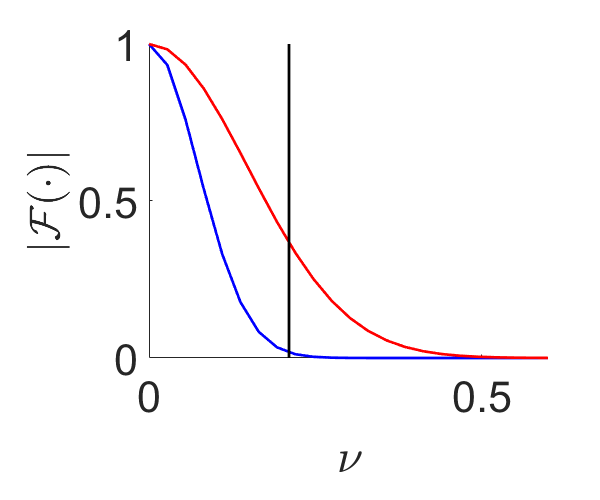

figure('Position',[100,100,600,500]);
plot(S,Freqresponse./Freqresponse(1),'b','Linewidth',2); hold on
plot(S,exp(-(S).^2/(Cutoff^2)),'r','Linewidth',2); hold on
plot([Cutoff Cutoff], [0 1], 'k','Linewidth',2)
xlabel('\nu')
axis([0 0.6 0 1])
SetFontSize(32)
ylabel('$$|\mathcal{F}(\cdot)|$$','Interpreter','latex','Fontsize',32)
TrimFig(0.9)
set(gca, 'Box', 'off' );

if savefigures == 'y'
        print -dpng -r600  ../../Figures/FreqResponse.png
end

BasisVar = 1/(2*Cutoff^2*pi^2)

BasisVar = 1.1433

tau = sqrt(2*Cutoff^2*pi^3)

tau = 1.6576

#### Basis functions selection

% Define basis function parameters

% Support length of basis functions
l = 3.5;
% Spatial limits on basis representation
smax = s(end)-l;    
smin = l;
[s1,s2] = meshgrid(s,s);

% Define field set up

%Basis decomposition
Basis.nx = 256;
% The following assures beating the Shannon's criterion by approx 1.25
[C1] = meshgrid(linspace(smin,smax,sqrt(Basis.nx)),linspace(smin,smax,sqrt(Basis.nx))); %16 x 16

Basis.mu1 = reshape(C1,1,[]);
Basis.mu2 = reshape(C1',1,[]);
Basis.tau(1:Basis.nx) = tau; %based on a cut-off frequency
Basis.sigma2(1:Basis.nx) = pi./(Basis.tau.^2);
Basis.phi = LocalisedKernelPhi(s1,s2,Basis.mu1,Basis.mu2,Basis.sigma2,Basis.sigma2);

% Events
callsAllEvents = [];
for i = 1:length(callsAllWeek)
    callsAllEvents = [callsAllEvents;callsAllWeek(i).Coords]; %coordinats of all events
end

% Define parameters

% Region boundaries
boundary = shaperead(fullfile(userpath,'Datos/Shp/Limite_vlc_planar.shp'));
% Basis functions parameters
rad = 1.3;
bgrate = -3.5;
limd = 500;

% Get Basis functions
Basis = FilterBasis(callsAllEvents, Basis, shift, scale, rad, bgrate, numWeeks, boundary.X, boundary.Y, limd);
save(fullfile(userpath,'SIDE/Data/Basis'))

load(fullfile(userpath,'SIDE/Data/Basis'))

Plot Basis Functions

% Boundary in geographic coordinates
boundaries_geo = shaperead(fullfile(userpath,'Datos/Shp/Limite_vlc.shp'), "UseGeoCoords", true);
neighborhoods_geo = shaperead(fullfile(userpath,'Datos/Shp/Barrios_vlc.shp'), "UseGeoCoords", true);
% Info about boundary in planar coordinates
info_planar = shapeinfo(fullfile(userpath,'Datos/Shp/Limite_vlc_planar.shp'));
% Get planar projection
proj = info_planar.CoordinateReferenceSystem;

% Up-sample basis function for map representation

% Define space
s = linspace(0,36,201);
% Delta space
ds = mean(diff(s));
% Coordinates grid
[s1,s2] = meshgrid(s);
% Get Basis functions
Basis.phi = LocalisedKernelPhi(s1,s2,Basis.mu1,Basis.mu2,Basis.sigma2,Basis.sigma2);
% True planar coordinates
strue1 = s.*scale(1) + shift(1);
strue2 = s.*scale(2) + shift(2);
[s1true,s2true] = meshgrid(strue1,strue2);
% Transfor true planar coordinates to geographic coordinates
[s1geo,s2geo] = projinv(proj,strue1,strue2);

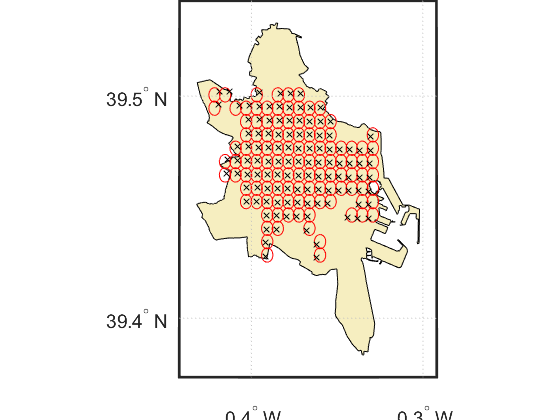

% Define Figure
figure()
axes('Position',[0 0 1 1],'Visible','off');
axes('Position',[.1 .1 .9 .9]);
% Plot boundary in geographic coordinates
plotGeoMap(boundaries_geo, 0)
% Retain plot
hold on
% Plot Basis Functions
for i = 1:Basis.nx
    % Plot influence areas
    [C,h] = contourm(s1geo,s2geo,Basis.phi(:,:,i),[1 exp(-1^2/2)],'r');
    % Re-project planar coordinates to geographic coordinates
    [mu_lat, mu_lon] = projinv(proj,Basis.mu1(i).*scale(1) + shift(1) ,Basis.mu2(i).*scale(2) + shift(2));
    % Plot centroids
    plotm(mu_lat,mu_lon,'kx') 
end
xlabel('Longitude','Fontsize',14)
ylabel('Latitude','Fontsize',14)
set(gca,'XTick',[])
set(gca,'YTick',[])


set(gcf,'PaperPositionMode','auto')

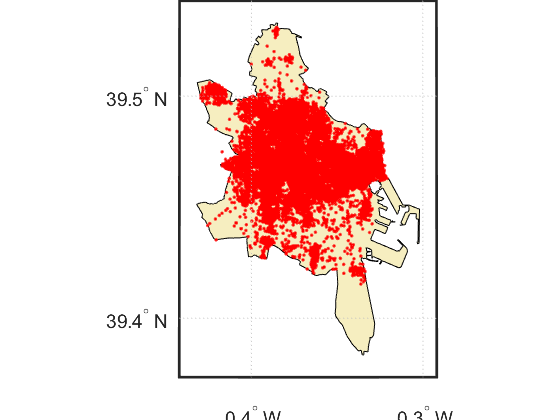

% Define Figure
figure()
axes('Position',[0 0 1 1],'Visible','off');
axes('Position',[.1 .1 .9 .9]);
% Plot boundary in geographic coordinates
plotGeoMap(boundaries_geo, 0)
% Retain plot
hold on
% Plot events per week
for k = 1:length(weekNum)-1
    [week_lat, week_lon] = projinv(proj, callsAllWeek(k).Coords(:,1).*scale(1) + shift(1), callsAllWeek(k).Coords(:,2).*scale(2) + shift(2));
    plotm(week_lat,week_lon,'r.')
end
% Set labels
xlabel('Longitude','Fontsize',14)
ylabel('Latitude','Fontsize',14)
set(gca,'XTick',[])
set(gca,'YTick',[])

xlabel('Lon')
ylabel('Lat')

load(fullfile(userpath,'SIDE/Data/Basis'));
load(fullfile(userpath,'SIDE/Data/callsAllDay'));
calls = readtable(fullfile(userpath,'Datos','calls_vlc.csv'));
warning('off')

### Purely Spatial Variation

Covariates effects

% Nonparametric kernel
sigmas1 = 250;
sigmas2 = 250;
GaussKernel = @(s1,s2,mu1,mu2) exp(-((s1-mu1).^2)./(2*sigmas1^2) - ((s2-mu2).^2)./(2*sigmas2^2));

N = length(callsAllDay);
s1_fine = -2:0.01:2;  % Spatial quadrature points
s2_fine = s1_fine;

Volume = FindVolume(s1_fine,s2_fine,GaussKernel)

Volume = 15.9997


% Setup space and time
s1 = 720800:50:732200;
s2 = 4362700:50:4379200;
[S1,S2] = meshgrid(s1,s2);
t = 1:N;

% Initialize
GRID = zeros(length(s2),length(s1));

for i = 1:N
    if ~isempty(callsAllDay(i).Coords)
    callsAllDay(i).Coords(isnan(callsAllDay(i).Coords(:,1)),:) = []; % remove NaNs
    for j = 1:length(callsAllDay(i).Coords(:,1))  % Place kernel at each point (ignore boundary effects for this map)
        GRID = GRID(:,:) + GaussKernel(S1,S2,callsAllDay(i).Coords(j,1),callsAllDay(i).Coords(j,2))/Volume;
    end
    end
end
%save('Spatial_nonparametric.mat')

% Mask of region
IN = inpolygon(S1,S2, boundary.X',boundary.Y');
min_intensity = 0.01;   % Treat extremely low intensities as 0 intensity
ds = mean(diff(s1));

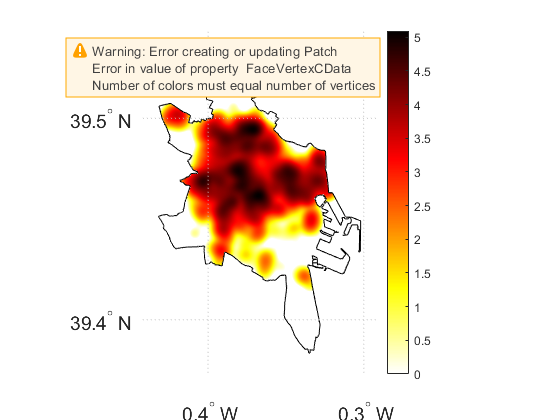

% Plot spatial intensity map
figure()
c = flipud(hot);
GRID = GRID.*IN;
plotGeoMap(boundaries_geo, 1)
[S1_lat, S2_lon] = projinv(proj, S1, S2);
surfm(S1_lat,S2_lon,log(GRID))
shading interp
colormap(c)
colorbar
caxis([0 max(max(log(GRID)))])
geoshow(boundaries_geo, 'FaceColor', [0.93 0.87 0.51], 'FaceAlpha', 0) 

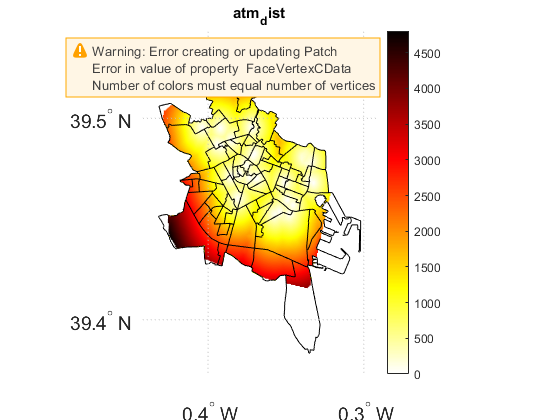

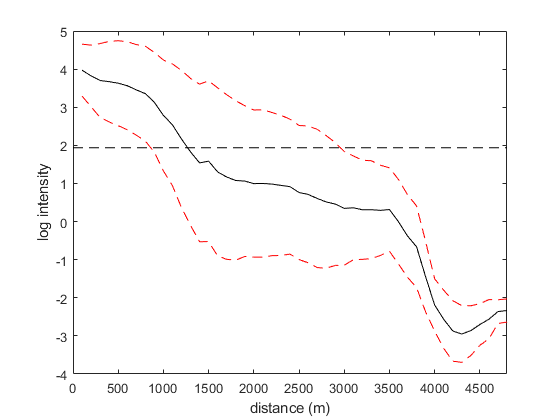

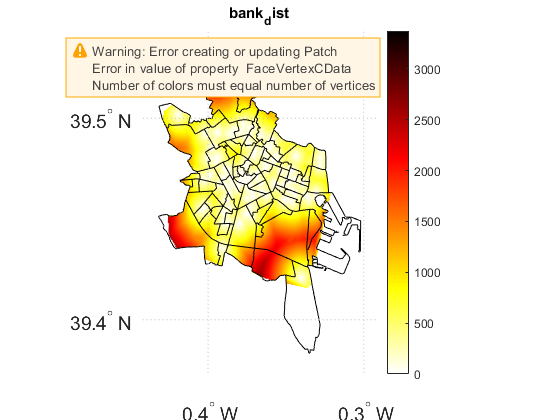

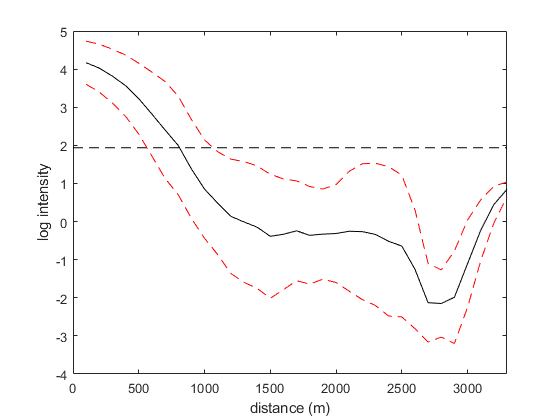

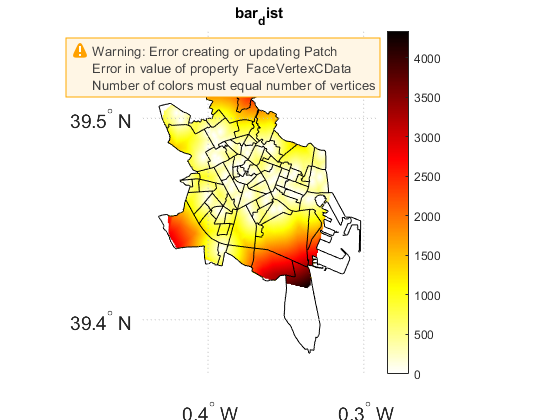

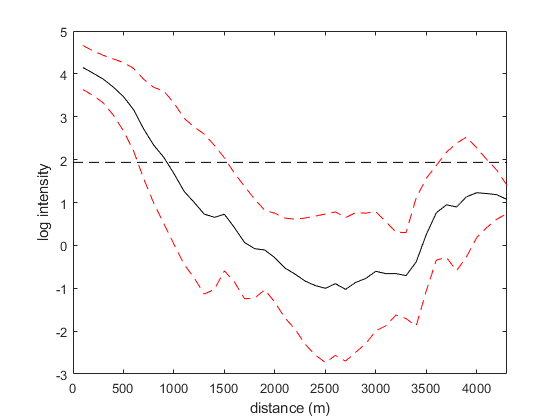

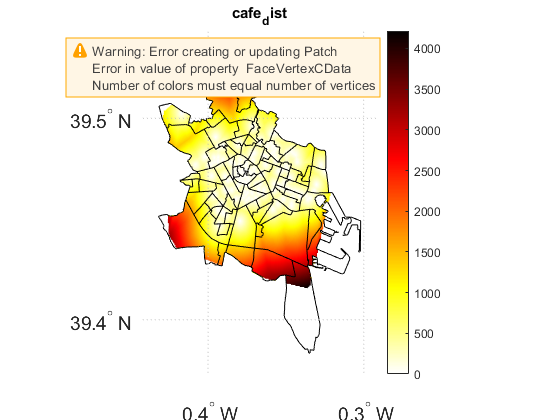

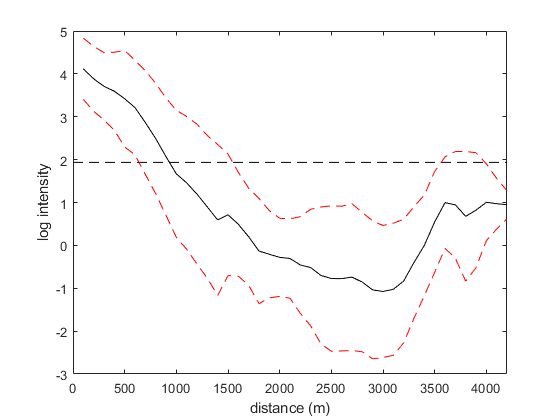

% Plot covariates correlations

% Get covariates names 
covnames = calls.Properties.VariableNames(1,5:15);

% Plot correlations
for i = 1:length(covnames)
    cov = plotCovariateMap(boundaries_geo, calls{:,"x"} , calls{:,"y"}, calls{:,covnames(1,i)}, IN, S1, S2 , S1_lat, S2_lon);
    geoshow(neighborhoods_geo, 'FaceColor', [0.93 0.87 0.51], 'FaceAlpha', 0) 
    title(covnames(1,i))
    Correlation_examine(0:100:max(max(cov)),cov,GRID,min_intensity) % Check only between 900 and 5000m
    xlabel('distance (m)'); ylabel('log intensity');
    set(gcf,'PaperPositionMode','auto');  
end

#### VB inference

% Load functions for VB
addpath(fullfile(userpath,'SIDE','Functions/netlab'));

% Define initial parameters
Estmu = 'n';            % No need to estimate "background" since this is implied from basis selection
Estprec = 'y';          % Estimate precision matrix (inv(SigmaW))
Estcovariates = 'y';    % Estimate covariates

%-----------------
% Setup constants
%-----------------

%Setup time
dt = 1;
N = numWeeks;
t = 0:dt:dt*(N-1);

%Setup space
J = 101;
s = linspace(0,36,J);
ds = (max(s)-min(s))/(J-1);
l=2;         %length of basis functions
smax = s(end)-l; %These are spatial limits on basis representation
smin = l;
[s1,s2] = meshgrid(s,s);

% Note: For analysis Afghanistan is roughly warped into a tightly fitting
% square with left-hand corner on the origin and length 36. This is set
% through the scale/shift parameters. This affine transformation is not
% necessary.

covnames = calls.Properties.VariableNames(1,5:15);

% Get covariates in locations
s1_scaled = s1.*scale(1)+ shift(1);
s2_scaled = s2.*scale(2)+ shift(2);

covariates_data = struct;
for i = 1:length(covnames)
    covariates_data(i).name = covnames(1,i);
    covariates_data(i).data = griddata(calls{:,"x"} , calls{:,"y"}, calls{:,covnames(1,i)}, s1_scaled , s2_scaled);
    covariates_data(i).data(isnan(covariates_data(i).data)) = nanmean(nanmean(covariates_data(i).data));
end

%Arrange in struct for par. passing
Constants.dt = dt;
Constants.ds = ds;
Constants.N = N;
Constants.t = t;
Constants.s = s;
Constants.s1 = s1;
Constants.s2 = s2;
Constants.smax = smax;
Constants.smin = smin;
Constants.J = J;
% Covariates
Constants.atm = covariates_data(1).data;
Constants.bank = covariates_data(2).data;
Constants.bar = covariates_data(3).data;
Constants.cafe = covariates_data(4).data;
Constants.ind = covariates_data(5).data;
Constants.mark = covariates_data(6).data;
Constants.night = covariates_data(7).data;
Constants.police = covariates_data(8).data;
Constants.pub = covariates_data(9).data;
Constants.rest = covariates_data(10).data;
Constants.taxi = covariates_data(11).data;

%-------------------------------------------------------------------
% Field setup
%-------------------------------------------------------------------

%Field noise
sigmaW = 0.25; % Rough estimate from temporal analysis, slightly de-tuned
sigmaR = 2;   % Observation noise, only used for linear regression on first time point

%Basis decomposition
Basis.inner = gaussinner(s1,s2,Basis.phi);      % Find the Gram matrix
Basis.Basisvec = zeros(J^2,Basis.nx);           % Vectorise
for i = 1:Basis.nx
    Basis.Basisvec(:,i) = reshape(Basis.phi(:,:,i),[],1);
end
Constants.d = Basis.nx;

%Setting up matrices and state-space model.
FieldMatrices.PSIx = Basis.inner;
FieldMatrices.W = dt*eye(Basis.nx);
FieldMatrices.R = sigmaR^2*eye(Basis.nx);

% --------------------
% Initialise variables
% --------------------
x = 3*ones(Basis.nx,numWeeks);          % Hidden states
numiters = 50;

% -------------------------------------------------------
% Initialise field estimate
% -------------------------------------------------------
Estinfo(1).xestpost = zeros(Basis.nx,1);        % Filtered estimate
Estinfo(1).xestprior = zeros(Basis.nx,1);       % Prior (for starting the scg) estimate
Estinfo(1).xestRTS = zeros(Basis.nx,1);         % Posterior (smoothed) estimate
Estinfo(1).PKalman = zeros(Basis.nx,Basis.nx);  % Filtered covariance
Estinfo(1).PRTS = zeros(Basis.nx,Basis.nx);     % Smoothed covariance
Estinfo = repmat(Estinfo(1),1,N);

% -------------------------------------------------------
% Initialise parameter estimate
% -------------------------------------------------------
Thetainfo(1).thetaest = zeros(Constants.d,1);
Thetainfo(1).vartheta = 1000*eye(Constants.d);
Thetainfo(1).muest = -3.5;
Thetainfo(1).varmu = 0;
Thetainfo(1).precisionest = repmat(1/(sigmaW^2),Basis.nx,1);  % Diagonal elements
Thetainfo(1).varprecision = repmat(1,Basis.nx,1);   
Thetainfo(1).Meanprecmat = 1/(sigmaW^2)*eye(Basis.nx);  % Whole matrix
Thetainfo(1).best = [-0.01,-0.01,-0.01,-0.01,-0.01,-0.01,-0.01,-0.01,-0.01,-0.01,-0.01]; % Covariate weights
Thetainfo(1).varb = [0 0 0 0 0 0 0 0 0 0 0];        

Thetainfo = repmat(Thetainfo(1),1,numiters);

% -------------------------------------------------------
% Point process parameters
% -------------------------------------------------------
beta = 1; % Dummy variable if set to 1
Constants.beta = beta;

%-----------------------------------------------
% Inference
%-----------------------------------------------

%Estimate initial condition
EstIntensity = DiggleContSpace(callsAllWeek(1).Coords, Constants, 8); % Nonparametric estimate of init condition
y = Regress(EstIntensity,Basis,Thetainfo(1).muest , beta);             % Regress onto chosen basis
% Now we assume that the regression is a prior estimate for a Kalman filter
% to do a one-step update
Estinfo(1) = KalmanFilter(y,Estinfo(1),Constants,FieldMatrices,Basis);

foptions = [0,1e-4,1e-4,1e-6,0,0,0,0,0,0,0,0,0,0,0,1e-8,0.1,0];

tic
for m = 2:200
    % VBE step
    Estinfo = VBEMSmoother_full_nonlinear(callsAllWeek,Constants,Estinfo,FieldMatrices,Basis,Thetainfo(m-1));
    % VBM step
    Thetainfo(m) = VBM(Estinfo,Thetainfo(m-1),FieldMatrices,Constants,Basis,callsAllWeek,Estmu,Estprec,Estcovariates);
    % Save temporary results for debugging
    save(fullfile(userpath,'SIDE/Data/Latest_4'))
    
    %Breaking Condition
    if norm(Thetainfo(m).thetaest - Thetainfo(m-1).thetaest) < 0.005 ...
            && (abs(Thetainfo(m).muest - Thetainfo(m-1).muest) < 0.01) ...
            && max(Thetainfo(m-1).precisionest./Thetainfo(m).precisionest) < 1.01 ...
            && min(Thetainfo(m-1).precisionest./Thetainfo(m).precisionest) > 0.99 ...
            && abs(Thetainfo(m).best(1) -Thetainfo(m-1).best(1)) < 0.005 ...
            && abs(Thetainfo(m).best(2) -Thetainfo(m-1).best(2)) < 0.005 ...
            && abs(Thetainfo(m).best(3) -Thetainfo(m-1).best(3)) < 0.005 ...
            && abs(Thetainfo(m).best(4) -Thetainfo(m-1).best(4)) < 0.005 ...
            && abs(Thetainfo(m).best(5) -Thetainfo(m-1).best(5)) < 0.005 ...
            && abs(Thetainfo(m).best(6) -Thetainfo(m-1).best(6)) < 0.005 ...
            && abs(Thetainfo(m).best(7) -Thetainfo(m-1).best(7)) < 0.005 ...
            && abs(Thetainfo(m).best(8) -Thetainfo(m-1).best(8)) < 0.005 ...
            && abs(Thetainfo(m).best(9) -Thetainfo(m-1).best(9)) < 0.005 ...
            && abs(Thetainfo(m).best(10) -Thetainfo(m-1).best(10)) < 0.005 ...
            && abs(Thetainfo(m).best(11) -Thetainfo(m-1).best(11)) < 0.005;
        break
    end
end
toc

load(fullfile(userpath,'SIDE/Data/Latest_4'));
addpath(fullfile(userpath,'SIDE','Functions'));

### Results

mu = Thetainfo(m).muest;

% Boundary in geographic coordinates
boundaries_geo = shaperead(fullfile(userpath,'Datos/Shp/Limite_vlc.shp'), "UseGeoCoords", true);
neighborhoods_geo = shaperead(fullfile(userpath,'Datos/Shp/Barrios_vlc.shp'), "UseGeoCoords", true);
% Region boundaries
boundary = shaperead(fullfile(userpath,'Datos/Shp/Limite_vlc_planar.shp'));
neighborhoods = shaperead(fullfile(userpath,'Datos/Shp/Barrios_vlc_planar.shp'));
% Info about boundary in planar coordinates
info_planar = shapeinfo(fullfile(userpath,'Datos/Shp/Limite_vlc_planar.shp'));
% Get planar projection
proj = info_planar.CoordinateReferenceSystem;

%Upsample Basis for higher resolution plotting and setup space
J2 = 201;
s = linspace(0,36,J2);
ds = mean(diff(s));
[s1,s2] = meshgrid(s);
strue1 = s.*scale(1) + shift(1);
strue2 = s.*scale(2) + shift(2);
[s1true,s2true] = meshgrid(strue1,strue2);
[S1_lat, S2_lon] = projinv(proj, s1true, s2true);
Basis.phi = LocalisedKernelPhi(s1,s2,Basis.mu1,Basis.mu2,Basis.sigma2,Basis.sigma2);
IN = inpolygons(s1true(:),s2true(:),boundary.X',boundary.Y');


#### Crime activity growth: Posterior mean fractional increase/decrease per week (2010-2019)

test = sum(multiprod(Basis.phi,reshape(Thetainfo(m).thetaest,1,1,Basis.nx)),3);
test = test.*(test>0);
test = reshape(test(:).*IN,size(test)); % Ignore components outside AFG

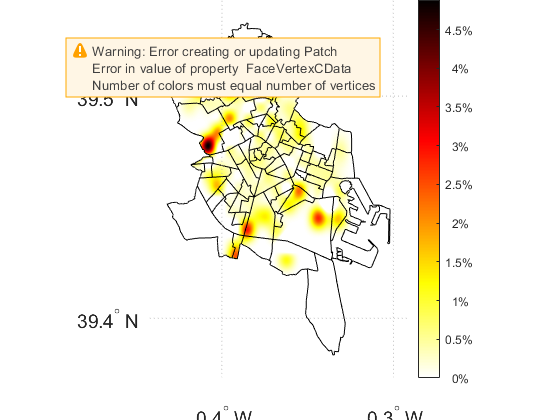

% Define Figure
figure()
axes('Position',[0 0 1 1],'Visible','off');
axes('Position',[.1 .1 .9 .9]);
% Plot boundary in geographic coordinates
plotGeoMap(boundaries_geo, 0)
c = flipud(hot);
% Retain plot
hold on
surfm(S1_lat, S2_lon, test)
shading interp
c = flipud(hot);
colormap(c);
h = colorbar;
labels = get(h,'xticklabel'); % get the y axis labels
labels_num = strcat(num2str(str2double(labels)*100), '%');
set(h,'xticklabel',labels_num);
%caxis([0, max(max(test))]);
geoshow(neighborhoods_geo, 'FaceColor', [0.93 0.87 0.51], 'FaceAlpha', 0)
hold off

test = sum(multiprod(Basis.phi,reshape(Thetainfo(m).thetaest,1,1,Basis.nx)),3);
test = test.*(test<0);
test = reshape(test(:).*IN,size(test)); % Ignore components outside AFG

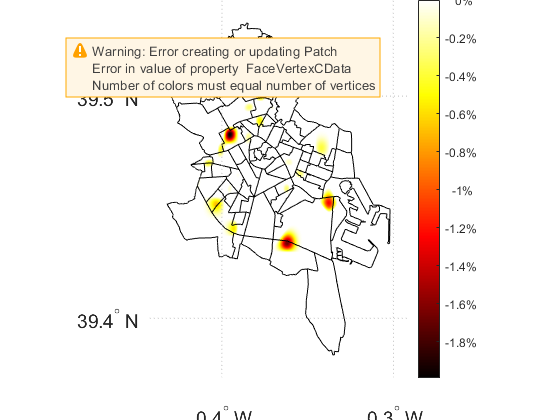

% Define Figure
figure()
axes('Position',[0 0 1 1],'Visible','off');
axes('Position',[.1 .1 .9 .9]);
% Plot boundary in geographic coordinates
plotGeoMap(boundaries_geo, 0)
c = flipud(hot);
% Retain plot
hold on
surfm(S1_lat, S2_lon, test)
shading interp
c = hot;
colormap(c);
h = colorbar;
labels = get(h,'xticklabel'); % get the y axis labels
labels_num = strcat(num2str(str2double(labels)*100), '%');
set(h,'xticklabel',labels_num);
%caxis([0, max(max(test))]);
geoshow(neighborhoods_geo, 'FaceColor', [0.93 0.87 0.51], 'FaceAlpha', 0)
hold off

#### Predictability/volatility map estimate

test = sum(multiprod(Basis.phi,reshape(diag(inv(Thetainfo(m).Meanprecmat)),1,1,Basis.nx)),3);
test = test.*(test>0);
test = reshape(test(:).*IN,size(test));

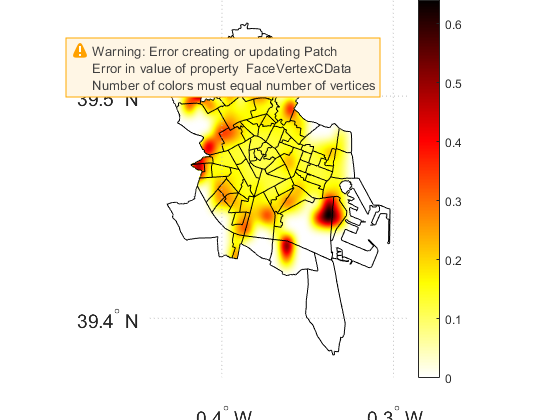

% Define Figure
figure()
axes('Position',[0 0 1 1],'Visible','off');
axes('Position',[.1 .1 .9 .9]);
% Plot boundary in geographic coordinates
plotGeoMap(boundaries_geo, 0)
c = flipud(hot);
% Retain plot
hold on
surfm(S1_lat, S2_lon, test);
shading interp
c = flipud(hot);
colormap(c);
h = colorbar;
%caxis([0.055,0.07]) % Only show where sigma2> 0.055 for visual purposes
geoshow(neighborhoods_geo, 'FaceColor', [0.93 0.87 0.51], 'FaceAlpha', 0)
hold off

#### Quantiles

%Rescale covariates
% Get covariates in locations
s1_scaled = s1.*scale(1)+ shift(1);
s2_scaled = s2.*scale(2)+ shift(2);

covariates_data = struct;
for i = 1:length(covnames)
    covariates_data(i).name = covnames(1,i);
    covariates_data(i).data = griddata(calls{:,"x"} , calls{:,"y"}, calls{:,covnames(1,i)}, s1_scaled , s2_scaled);
    covariates_data(i).data(isnan(covariates_data(i).data)) = nanmean(nanmean(covariates_data(i).data));
end

% Initialize
Uest = zeros(J2,J2,N); Umedian = zeros(J2,J2,N); Uupper = zeros(J2,J2,N); Ulower = zeros(J2,J2,N);
intensityest = zeros(J2,J2,N); int_median = zeros(J2,J2,N); int_upper = zeros(J2,J2,N); int_lower  = zeros(J2,J2,N);

% Find required quantiles
for i = 1:numWeeks
    Uest(:,:,i) = sum(multiprod(Basis.phi,reshape(Estinfo(i).xestRTS+diag(Estinfo(i).PRTS)./2,1,1,Basis.nx)),3);
    Umedian(:,:,i) = sum(multiprod(Basis.phi,reshape(Estinfo(i).xestRTS,1,1,Basis.nx)),3);
    Uupper(:,:,i) = sum(multiprod(Basis.phi,reshape(Estinfo(i).xestRTS + 0.65*sqrt(diag(Estinfo(i).PRTS)),1,1,Basis.nx)),3);
    Ulower(:,:,i) = sum(multiprod(Basis.phi,reshape(Estinfo(i).xestRTS - 0.65*sqrt(diag(Estinfo(i).PRTS)),1,1,Basis.nx)),3);
    
    Covariates = Thetainfo(m).best(1)*covariates_data(1).data + Thetainfo(m).varb(1)*covariates_data(1).data.^2/2 + ...
               Thetainfo(m).best(2)*covariates_data(2).data + Thetainfo(m).varb(2)*covariates_data(2).data.^2./2 + ...
               Thetainfo(m).best(3)*covariates_data(3).data + Thetainfo(m).varb(3)*covariates_data(3).data.^2./2 + ...
               Thetainfo(m).best(4)*covariates_data(4).data + Thetainfo(m).varb(4)*covariates_data(4).data.^2./2 + ...
               Thetainfo(m).best(5)*covariates_data(5).data + Thetainfo(m).varb(5)*covariates_data(5).data.^2./2 + ...
               Thetainfo(m).best(6)*covariates_data(6).data + Thetainfo(m).varb(6)*covariates_data(6).data.^2./2 + ...
               Thetainfo(m).best(7)*covariates_data(7).data + Thetainfo(m).varb(7)*covariates_data(7).data.^2./2 + ...
               Thetainfo(m).best(8)*covariates_data(8).data + Thetainfo(m).varb(8)*covariates_data(8).data.^2./2 + ...
               Thetainfo(m).best(9)*covariates_data(9).data + Thetainfo(m).varb(9)*covariates_data(9).data.^2./2 + ...
               Thetainfo(m).best(11)*covariates_data(11).data + Thetainfo(m).varb(11)*covariates_data(11).data.^2./2 + ...
               Thetainfo(m).best(10)*covariates_data(10).data + Thetainfo(m).varb(10)*covariates_data(10).data .^2./2;
    
    intensityest(:,:,i) = exp(mu + Covariates+ Uest(:,:,i));
    int_median(:,:,i) = exp(mu + Covariates+ Umedian(:,:,i));
    int_upper(:,:,i) = exp(mu + Covariates+ Uupper(:,:,i));
    int_lower(:,:,i) = exp(mu + Covariates+ Ulower(:,:,i));
end

%save(fullfile(userpath,'SIDE/Data/Quantile_data_4'),'int_lower','int_median','int_upper','intensityest')
load(fullfile(userpath,'SIDE/Data/Quantile_data_4'),'int_lower','int_median','int_upper','intensityest')

% Neighborhoods
neighborhoods_names = ["RUSSAFA","BENICALAP","CABANYAL-CANYAMELAR","TORREFIEL", "ARRANCAPINS","ELS ORRIOLS", "NOU MOLES", "LA MALVA-ROSA"];
index_nei = [];
for nom = 1:length(neighborhoods)
    if ismember(neighborhoods(nom).nombre, neighborhoods_names);
        index_nei = [index_nei, nom];
    end
end

data_nei = struct;
for ind = 1:length(index_nei)
    data_nei(ind).lcorner = neighborhoods(index_nei(ind)).BoundingBox(1,:) - 100;
    data_nei(ind).ucorner = neighborhoods(index_nei(ind)).BoundingBox(2,:) + 100;
end

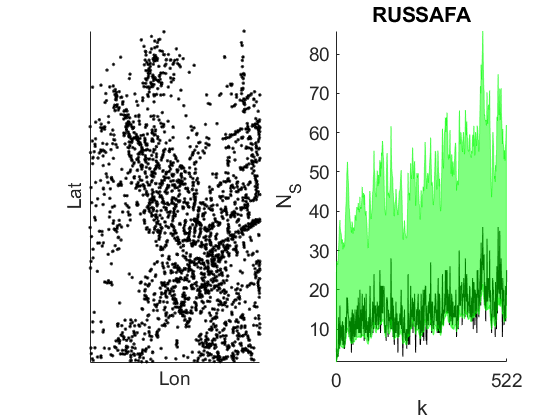

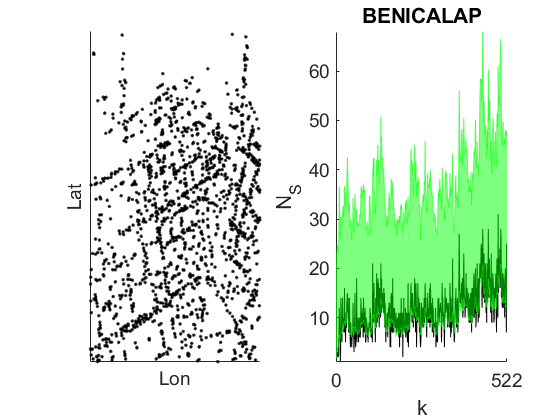

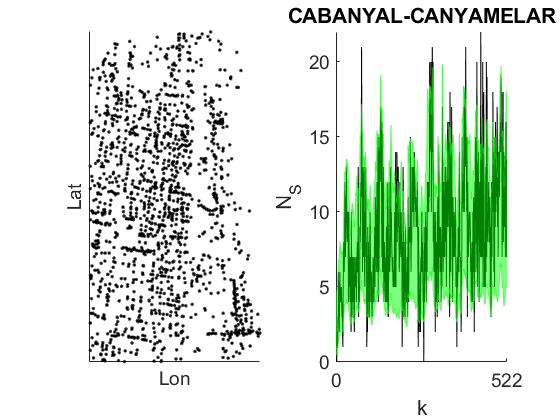

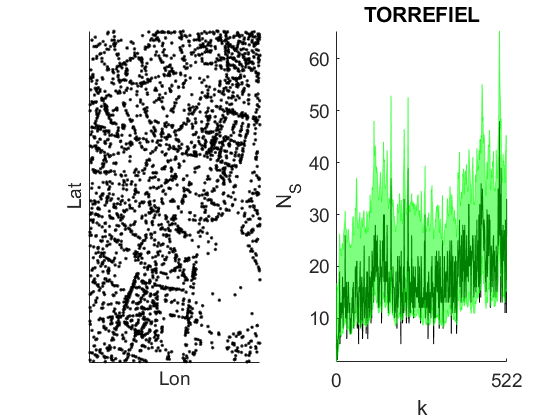

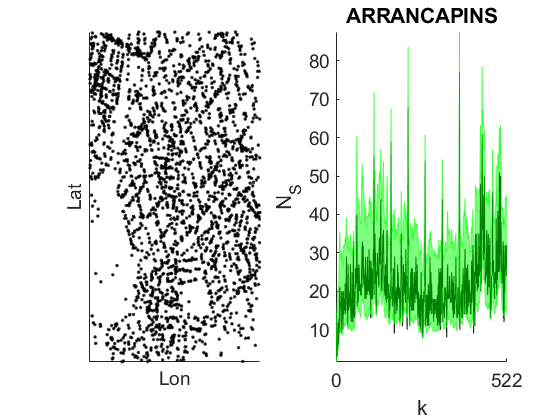

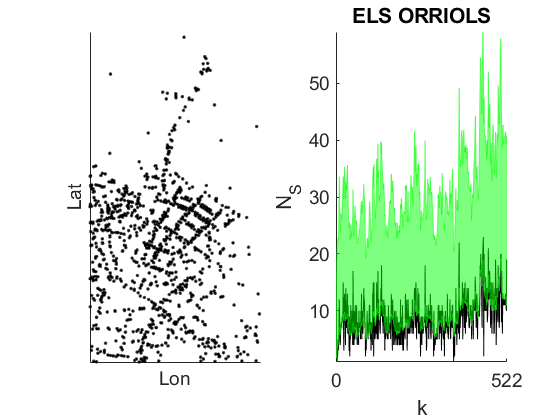

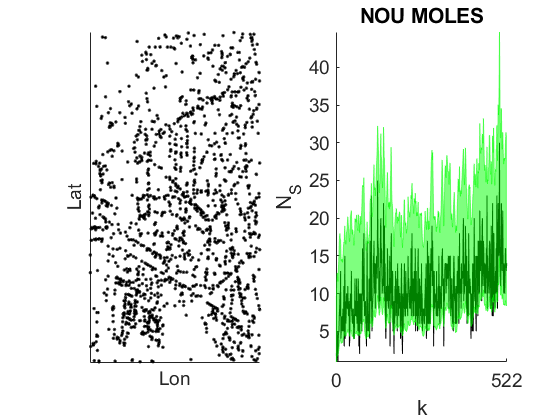

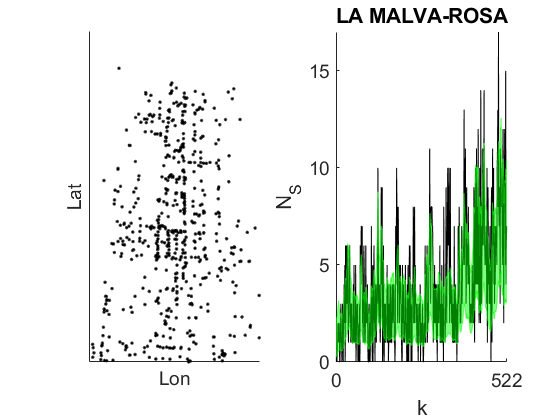

for city = 1:length(data_nei)
    figure()
    Analyzecity(strue1,strue2,data_nei(city).lcorner,data_nei(city).ucorner,callsAllDay,int_lower,int_median,int_upper,ds)
    title(neighborhoods_names(city))
end

load(fullfile(userpath,'SIDE/Data/Results_prec_16'))

### Prediction Section

% Load results from VB

% Adopt marginal variance
DisturbVar = inv(diag(diag(Thetainfo(m).Meanprecmat)));

% Define variables

N= 2000;                            % Number of samples
xsample2019 = zeros(Basis.nx,52);   % Samples for 52 weeks, state in 2010
fieldsample2019 = zeros(J,J,52);    % Sample field in 2010
intsample2019 = zeros(J,J,52);      % Sample intensity in 2010
xsample2020 = zeros(Basis.nx,52);   % Sample state in 2011
fieldsample2020 = zeros(J,J,52);    % Sample field in 2011
intsample2020 = zeros(J,J,52);      % Sample intensity in 2011

% Load boundaries
neighborhoods_geo = shaperead(fullfile(userpath,'Datos/Shp/Barrios_vlc.shp'), "UseGeoCoords", true);
% Info about boundary in planar coordinates
info_planar = shapeinfo(fullfile(userpath,'Datos/Shp/Limite_vlc_planar.shp'));
% Get planar projection
proj = info_planar.CoordinateReferenceSystem;

% set up space
J = 101;
s = linspace(0,36,J);
ds = mean(diff(s));
[s1,s2] = meshgrid(s);
strue1 = s.*scale(1) + shift(1);
strue2 = s.*scale(2) + shift(2);
[s1true,s2true] = meshgrid(strue1,strue2);
[S1_lat, S2_lon] = projinv(proj, s1true, s2true);
Basis.phi = LocalisedKernelPhi(s1,s2,Basis.mu1,Basis.mu2,Basis.sigma2,Basis.sigma2);

% Neighborhoods mask
Provmask = zeros(J^2,length(neighborhoods_geo));
for Pnum = 1:length(neighborhoods_geo)
    Provmask(:,Pnum) = inpolygon(S1_lat(:),S2_lon(:),neighborhoods_geo(Pnum).Lat',neighborhoods_geo(Pnum).Lon');
    Provname(Pnum).str = neighborhoods_geo(Pnum).nombre;
end

Provintensity2019 = zeros(length(neighborhoods_geo),N);    % Provincial intensity in 2009
Count2019 = zeros(length(neighborhoods_geo),N);            % Provincial count in 2009
Provintensity2020 = zeros(length(neighborhoods_geo),N);    % Provincial intensity in 2010
Count2020 = zeros(length(neighborhoods_geo),N);            % Provincial count in 2010
Growth = zeros(length(neighborhoods_geo),N);               % Sample provincial growth

% Get covariates in locations
covariates_data = struct;
for i = 1:length(covnames)
    covariates_data(i).name = covnames(1,i);
    covariates_data(i).data = griddata(calls{:,"x"} , calls{:,"y"}, calls{:,covnames(1,i)}, s1true , s2true);
    covariates_data(i).data(isnan(covariates_data(i).data)) = nanmean(nanmean(covariates_data(i).data));
end

% Fixed effects on intensity field
Covariates = Thetainfo(m).best(1)*covariates_data(1).data + Thetainfo(m).varb(1)*covariates_data(1).data.^2/2 + ...
               Thetainfo(m).best(2)*covariates_data(2).data + Thetainfo(m).varb(2)*covariates_data(2).data.^2./2 + ...
               Thetainfo(m).best(3)*covariates_data(3).data + Thetainfo(m).varb(3)*covariates_data(3).data.^2./2 + ...
               Thetainfo(m).best(4)*covariates_data(4).data + Thetainfo(m).varb(4)*covariates_data(4).data.^2./2 + ...
               Thetainfo(m).best(5)*covariates_data(5).data + Thetainfo(m).varb(5)*covariates_data(5).data.^2./2 + ...
               Thetainfo(m).best(6)*covariates_data(6).data + Thetainfo(m).varb(6)*covariates_data(6).data.^2./2 + ...
               Thetainfo(m).best(7)*covariates_data(7).data + Thetainfo(m).varb(7)*covariates_data(7).data.^2./2 + ...
               Thetainfo(m).best(8)*covariates_data(8).data + Thetainfo(m).varb(8)*covariates_data(8).data.^2./2 + ...
               Thetainfo(m).best(9)*covariates_data(9).data + Thetainfo(m).varb(9)*covariates_data(9).data.^2./2 + ...
               Thetainfo(m).best(11)*covariates_data(11).data + Thetainfo(m).varb(11)*covariates_data(11).data.^2./2 + ...
               Thetainfo(m).best(10)*covariates_data(10).data + Thetainfo(m).varb(10)*covariates_data(10).data .^2./2;


% Main Monte Carlo routine for intensity in each province            
for i = 1:N
    for j = 469:520
        %Sample x
        xsample2019(:,j-468) = mvnrnd(Estinfo(j).xestRTS,diag(diag(Estinfo(j).PRTS)));
        fieldsample2019(:,:,j-468) = sum(multiprod(Basis.phi,reshape(xsample2019(:,j-468),1,1,Basis.nx)),3);
        intsample2019(:,:,j-468) = exp(fieldsample2019(:,:,j-468) + Thetainfo(m).muest + Covariates);
    end
    TotIntensity2019 = sum(intsample2019,3);
    for Pnum = 1:length(neighborhoods_geo)
        Provintensity2019(Pnum,i) = sum(sum(reshape(TotIntensity2019(:).*Provmask(:,Pnum),length(s),[])))*ds^2;
        Count2019(Pnum,i) = poissrnd(Provintensity2019(Pnum,i));
    end
    xsample2020(:,1) = xsample2019(:,end);
    fieldsample2020(:,:,1) = fieldsample2019(:,:,end);
    intsample2020(:,:,1) = intsample2019(:,:,end);
    for j = 2:41
        xsample2020(:,j) = xsample2020(:,j-1) + Thetainfo(m).thetaest + mvnrnd(zeros(Basis.nx,1),DisturbVar)';
        fieldsample2020(:,:,j) = sum(multiprod(Basis.phi,reshape(xsample2020(:,j),1,1,Basis.nx)),3);
        intsample2020(:,:,j) = exp(fieldsample2020(:,:,j) + Thetainfo(m).muest + Covariates);
    end
    TotIntensity2020 = sum(intsample2020,3);
    for Pnum = 1:length(neighborhoods_geo)
        Provintensity2020(Pnum,i) = sum(sum(reshape(TotIntensity2020(:).*Provmask(:,Pnum),length(s),[])))*ds^2;
        Count2020(Pnum,i) = poissrnd(Provintensity2020(Pnum,i));
        Growth(Pnum,i) = Count2020(Pnum,i)/Count2019(Pnum,i);
    end
    i
end

load(fullfile(userpath,'SIDE/Data/Growth2019_2020_Cov'));
%load(fullfile(userpath,'SIDE/Data/Growth2019_2020_Cov'));
%load(fullfile(userpath,'SIDE/Data/Growth2019_2020_Cov_40_weeks'));

%Prediction
Count2019(Count2019 == 0) = 1;
Count2020(Count2020 == 0) = 1;
ModelCount2019 = Count2019;
ModelCount2020 = Count2020;

% Data
Count2019Val = [5;11;3;444;467;113;137;194;152;50;183;127;58;175;70;130;47;73;45;124;120;173;62;377;164;69;177;93;284;119;83;81;270;313;170;170;288;27;208;508;141;123;174;188;77;133;135;166;57;177;77;175;75;97;42;40;86;82;21;45;157;221;79;33;162;20;91;326;90;58;301;54;39;64;276;100;13;29;35;9;76];
Count2020Val = [5;4;4;320;252;54;61;149;84;30;115;49;34;118;46;72;16;61;15;58;86;106;46;204;104;29;80;61;194;87;42;44;175;177;123;117;195;16;127;298;75;79;126;143;58;74;89;93;41;128;63;130;53;84;27;20;72;45;17;21;89;142;65;27;107;21;45;222;65;45;167;37;30;51;171;66;9;19;51;6;59];

% Simple linear predictor with no offset
Prediction = ModelCount2020./ModelCount2019.*repmat(Count2019Val,1,N);

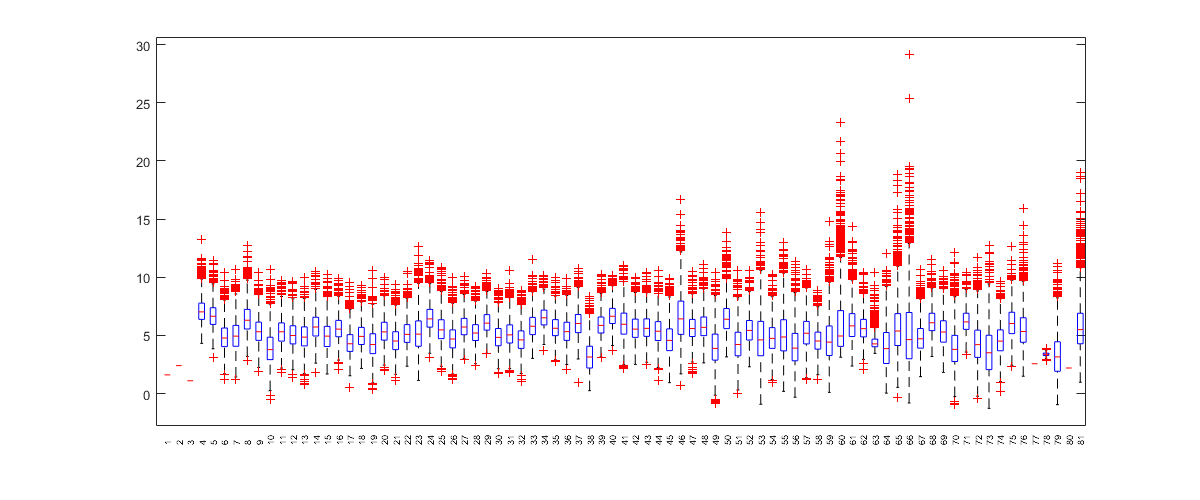

figure('Position',[100,100,1200,500]); hold on;
for i = 1:length(Provname)
    Provname(i).strnum = strcat(num2str(i));
end
boxplot(log(Prediction'),{Provname(:).strnum},'labelorientation','inline'); 
hold on;
set(findobj(gca,'Type','text'),'FontSize',7)

% We are analyzing the log of the counts to stabilize the variances
plot(log(Count2020Val),'go','Linewidth',2)
Prediction(Prediction == 0) = 1;
Prediction(Prediction == Inf) = 1;
meanlogPred = mean(log(Prediction'))';
plot(meanlogPred,'ko','Linewidth',2)
ylabel('log calls activity in 2020')
% set(gca,'YScale','log')
[r,p] = corrcoef(Count2020Val,median(Prediction')');
[r2,p2] = corrcoef(median(log(Prediction'))',log(Count2020Val));
set(gcf,'PaperPositionMode','auto')
print -dpng -r300 Predictions.png

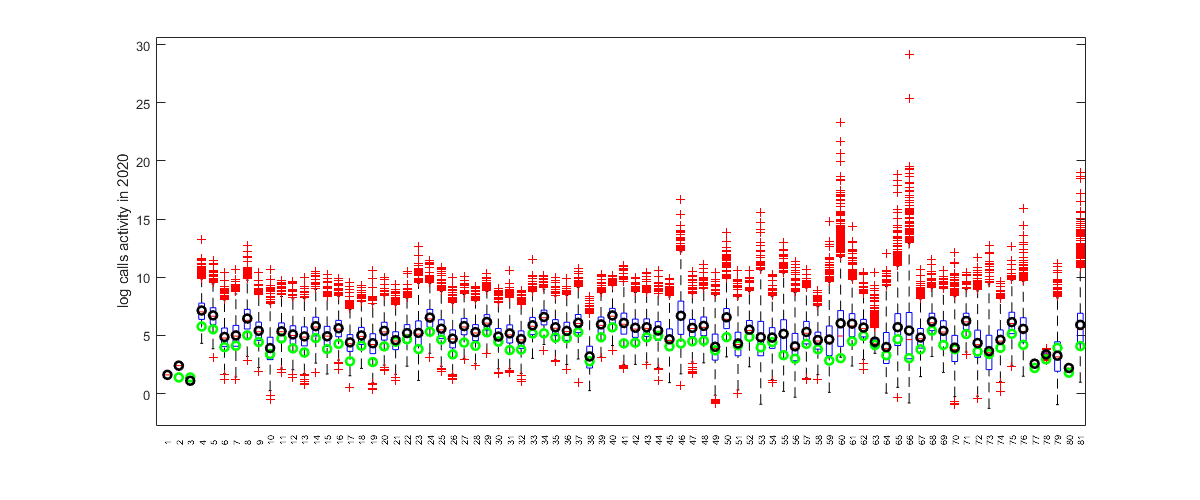

% We are analyzing the log of the counts to stabilize the variances
plot(log(Count2020Val),'go','Linewidth',2)
Prediction(Prediction == 0) = 1;
Prediction(Prediction == Inf) = 1;
meanlogPred = mean(log(Prediction'))';
plot(meanlogPred,'ko','Linewidth',2)
ylabel('log calls activity in 2020')
% set(gca,'YScale','log')
[r,p] = corrcoef(Count2020Val,median(Prediction')');
[r2,p2] = corrcoef(median(log(Prediction'))',log(Count2020Val));
set(gcf,'PaperPositionMode','auto')
print -dpng -r300 Predictions.png

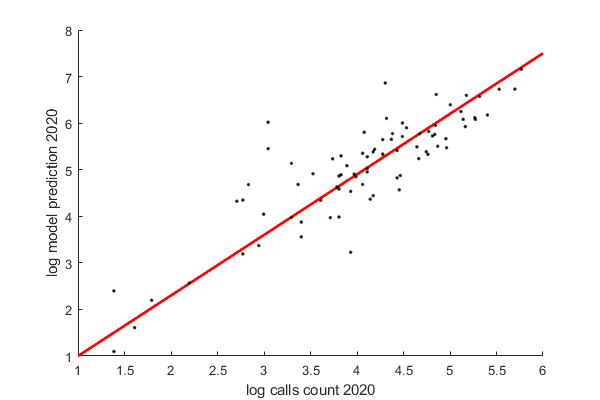

% Point prediction comparison
figure('Position',[100 100 600 400]); hold on;
plot([1;6],[1;7.5],'r','Linewidth',2)
scatter(log(Count2020Val),mean(log(Prediction)')','k.','Linewidth',2)
xlabel('log calls count 2020')
ylabel('log model prediction 2020')
print -dpng -r300 Linearprediction.png

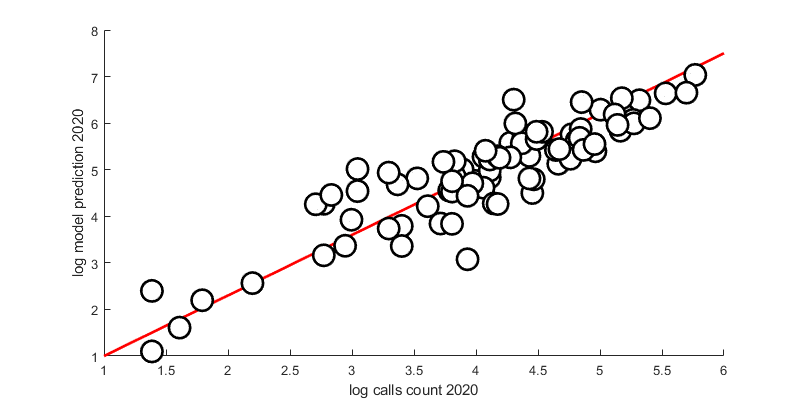

% Label points
figure('Position',[100 100 800 400]); hold on;
plot([1;6],[1;7.5],'r','Linewidth',2)
hold on
for i = 1:length(Provname)
    plot(log(Count2020Val(i)),median(log(Prediction(i,:)))','ko','Linewidth',2)
end
% Now get the points in the order in which they were plotted
ln = flipud(get(gca,'children'));  % ln(1) was plotted first.
% Now label them.
set(ln,'markers',16,'markerfa','w')
for ii = 2:length(ln)
        D = get(ln(ii),{'xdata','ydata'});
        S = sprintf('%i',ii-1);  % Second marker is first province
        T = text(D{1}-.04 * length(S),D{2},S) ;
        set(T,'fontsize',8,'color','k')
end
xlabel('log calls count 2020')
ylabel('log model prediction 2020')
set(gcf,'PaperPositionMode','auto')
print -dpng -r600 Linearprediction_need_modif.png

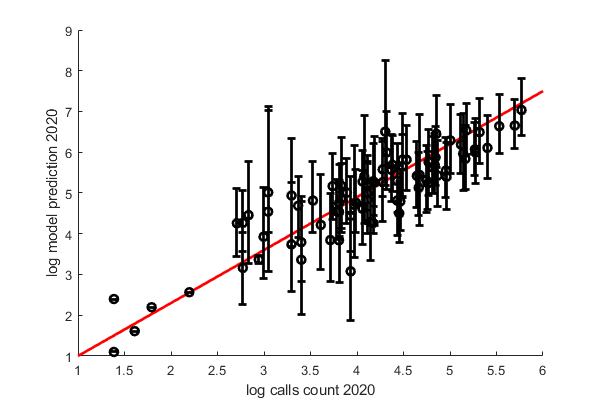

% Point prediction with confidence intervals
figure('Position',[100 100 600 400]); hold on;
plot([1;6],[1;7.5],'r','Linewidth',2)
errorbar(log(Count2020Val),log(median(Prediction')'),...
    log(median(Prediction')')-log(quantile(Prediction',0.25)'),...
    log(quantile(Prediction',0.75)') - log(median(Prediction')'),'ko','Linewidth',2)
xlabel('log calls count 2020')
ylabel('log model prediction 2020')

quantileRange = (log(quantile(Prediction',0.75)') - log(median(Prediction')')) - (log(median(Prediction')')-log(quantile(Prediction',0.25)'));
meanQuantileRange = mean(quantileRange);
% cities with high variances
citiesHigh = [];
for i=1:length(quantileRange)
    if quantileRange(i) > meanQuantileRange
        citiesHigh = [citiesHigh, i];
    end
end

% select spatial boundaries
data_cities = struct;
for ind = 1:length(citiesHigh)
    data_cities(ind).lcorner = neighborhoods(citiesHigh(ind)).BoundingBox(1,:) - 100;
    data_cities(ind).ucorner = neighborhoods(citiesHigh(ind)).BoundingBox(2,:) + 100;
    data_cities(ind).name = neighborhoods(citiesHigh(ind)).nombre;
end
% plot historic and confidence intervals
for city = 1:length(data_cities)
    figure()
    Analyzecity(strue1,strue2,data_cities(city).lcorner,data_cities(city).ucorner,callsAllDay,int_lower,int_median,int_upper,ds)
    title(data_cities(city).name)
end

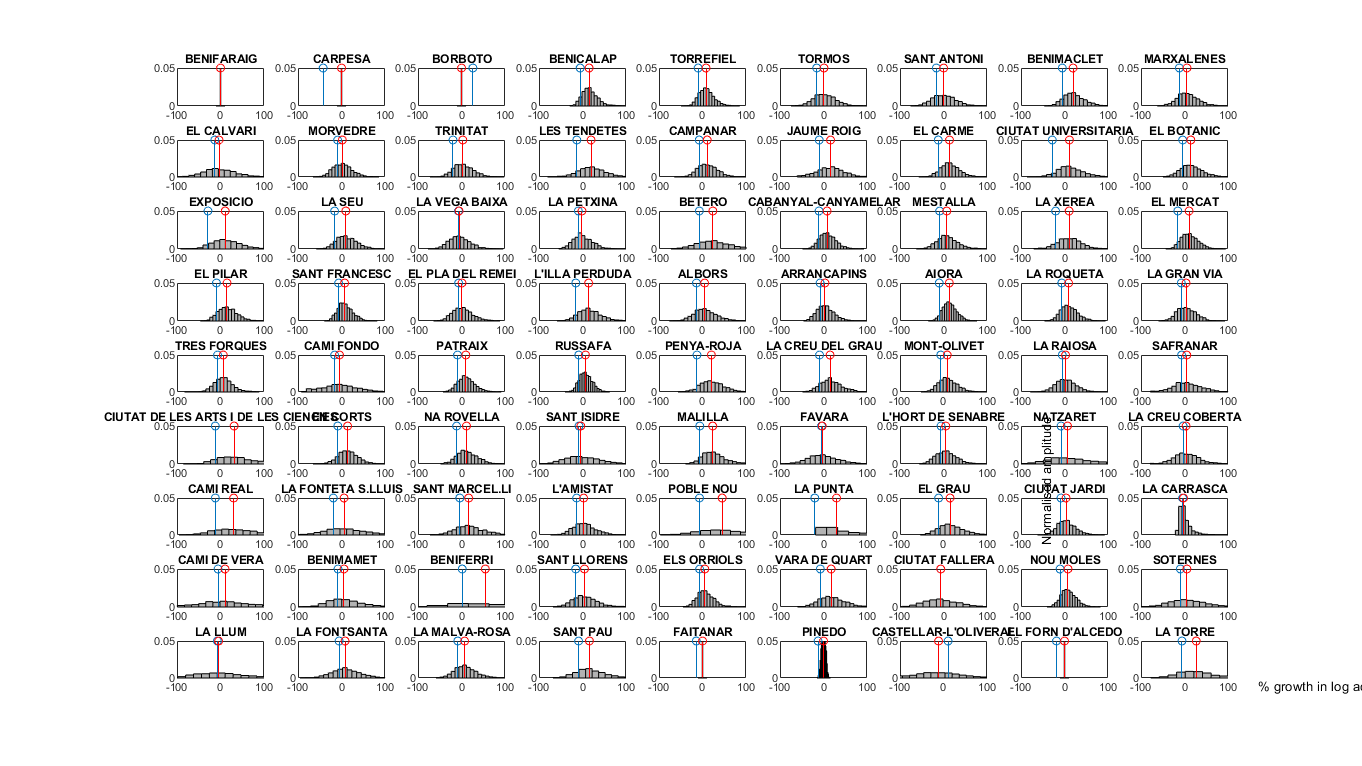

% Histograms of log values
figure('units','normalized','outerposition',[0 0 1 1])
Pred_growth =  ((log(Prediction) - repmat(log(Count2019Val),1,N)))./(repmat(log(Count2019Val),1,N));
Act_growth = (log(Count2020Val) - log(Count2019Val))./log(Count2019Val);
Perc_change = [Act_growth,quantile(Pred_growth',[0.1,0.5,0.9])'];
for i = 1:length(Provname)
    subplot(9,9,i)
    histnorm(Pred_growth(i,:)*100,21); hold on
    h = findobj(gca,'Type','patch');
    set(h,'FaceColor',[0.7 0.7 0.7],'EdgeColor','k')
    %    histfit(Pred_growth(i,:)); hold on
    stem(Act_growth(i)*100,0.05);
    stem(median(Pred_growth(i,:))*100,0.05,'r');
    title(Provname(i).str,'Fontsize',5)
    axis([-100 100 0 0.05])
    set(gca,'Fontsize',8)
end
text(170,-0.01,'% growth in log activity count')
text(-320,0.18,'Normalised amplitude','rotation',90)

set(gcf,'PaperPositionMode','auto')

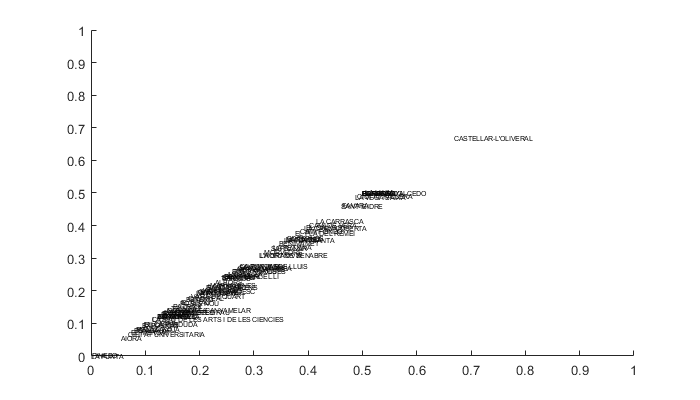

figure('Position',[100,100,700,400])
quantile_test = 0:0.0001:1; %Any smaller step size is noisy
classa =zeros(size(quantile_test));

for i = 1:length(Provname)
    prov_quantiles = quantile(Pred_growth(i,:),quantile_test);
    closest_quant_ind = find(abs(prov_quantiles - Act_growth(i)) == min(abs(prov_quantiles - Act_growth(i))));
    closest_quant_ind = closest_quant_ind(round(length(closest_quant_ind)/2));
    classa(abs(closest_quant_ind(1) - find(quantile_test == 0.5))*2 + 1) = classa(abs(closest_quant_ind(1) - find(quantile_test == 0.5))+1) + 1;
    text(quantile_test(closest_quant_ind),quantile_test(closest_quant_ind),Provname(i).str,'Fontsize',5)
end

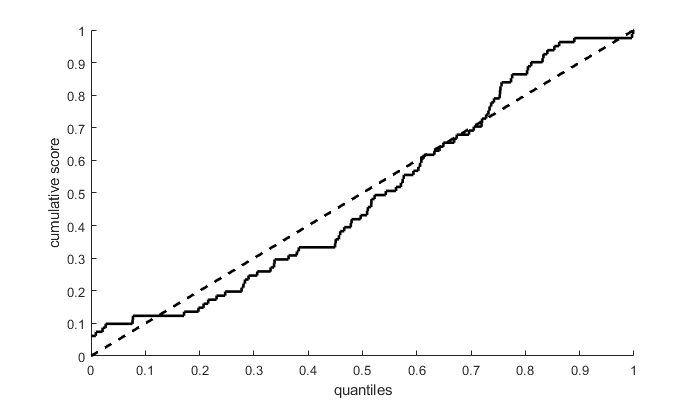


plot(quantile_test,cumsum(classa)/length(Provname),'k','Linewidth',2); hold on
plot([0 1],[0 1],'k--','Linewidth',2)
xlabel('quantiles'); ylabel('cumulative score'); box off

set(gcf,'PaperPositionMode','auto')